human_size = load('allhumandata.mat');human_size = human_size.humandata;

% Human Analysis from Separate Data
% calculate sum of retinal (removing v7), parietal, and frontal areas
for i = 1:2
    surfacearea_smoothwm{i} = [human_size.retino_surfacearea_smoothwm{i}([1:13,15:18],:);human_size.parietal_surfacearea_smoothwm{i}];
    surfacearea_pial{i} = [human_size.retino_surfacearea_pial{i}([1:13,15:18],:);human_size.parietal_surfacearea_pial{i}];
end

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
human_surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

human_bothhemi_SA = [human_surfacearea_avg{1} + human_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(human_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(human_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(human_bothhemi_SA(5:6,:),1);

SA_sumvd_human = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;human_bothhemi_SA(7:end,:)];

human_all = SA_sumvd_human;


monks=load('Monks/alldata.mat');

monks_avg_lh = (monks.retino_surfacearea_pial_lh + monks.retino_surfacearea_smoothwm_lh)/2;
monks_avg_rh = (monks.retino_surfacearea_pial_rh + monks.retino_surfacearea_smoothwm_rh)/2;
monks_bothhemis = [monks_avg_rh, monks_avg_lh];

% restructure summed hemisphere data to get area categories we want to display
V1_bothhemis_sumvd = sum(monks_bothhemis(1:2,:),1);
V2_bothhemis_sumvd = sum(monks_bothhemis(3:4,:),1);
V3_bothhemis_sumvd = sum(monks_bothhemis(5:6,:),1);
V4_bothhemis_sumvd = sum(monks_bothhemis(7:8,:),1);
V4A_bothhemis_sumvd = sum(monks_bothhemis(9:10,:),1);

SA_sumvd_monkey = [V1_bothhemis_sumvd;V2_bothhemis_sumvd;...
    V3_bothhemis_sumvd;V4_bothhemis_sumvd;V4A_bothhemis_sumvd;monks_bothhemis(11:end,:)];

monkey_all = SA_sumvd_monkey;


neo_size = load('Humans/NeonatalComparison/allvisualareadata.mat');

surfacearea_smoothwm{1} = neo_size.allsubjs_smoothwm_rh([2:14,16:end],:);surfacearea_smoothwm{2} = neo_size.allsubjs_smoothwm_lh([2:14,16:end],:);
surfacearea_pial{1} = neo_size.allsubjs_pial_rh([2:14,16:end],:);surfacearea_pial{2} = neo_size.allsubjs_pial_lh([2:14,16:end],:);

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
neo_surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

neo_bothhemi_SA = [neo_surfacearea_avg{1} + neo_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(neo_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(neo_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(neo_bothhemi_SA(5:6,:),1);

SA_sumvd_neo = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;neo_bothhemi_SA(7:end,:)];

neo_all = SA_sumvd_neo;

human_dorsal_idx =  [1, 2, 3, 9, 10, 15:21];
human_lateral_idx = [1, 2, 3, 11:14];
human_ventral_idx = [1, 2, 3, 4:8];

monkey_dorsal_idx =  [1, 2, 3, 4, 5, 11:17];
monkey_lateral_idx = [1, 2, 3, 4, 5, 18:21];
monkey_ventral_idx = [1, 2, 3, 4, 5, 6:10];

evc_idx = 2:3;
v4_idx = 4;
dorsal_idx = human_dorsal_idx(4:5);
parietal_idx = human_dorsal_idx(6:end);
lateral_idx = human_lateral_idx(4:end);
ventral_idx = human_ventral_idx(5:end);
human_area_idx = {evc_idx,v4_idx,ventral_idx,dorsal_idx,lateral_idx,parietal_idx};

evc_idx = 2:3;
v4_idx = 4:5;
dorsal_idx = monkey_dorsal_idx(6:7);
parietal_idx = monkey_dorsal_idx(8:end);
lateral_idx = monkey_lateral_idx(6:end);
ventral_idx = monkey_ventral_idx(6:end);
monkey_area_idx = {evc_idx,v4_idx,ventral_idx,dorsal_idx,lateral_idx,parietal_idx};

nResampling = 1000;
d = 1:size(human_all,2);
data_monkey = zeros(length(human_area_idx),nResampling);
for idx = 1:length(human_area_idx)
    for res = 1:nResampling
        y = datasample(d,size(monkey_all,2));
        data_monkey(idx,res) = mean(mean(human_all(human_area_idx{idx},y)./human_all(1,y),2,'omitnan'))./mean(mean(monkey_all(monkey_area_idx{idx},:)./monkey_all(1,:),2,'omitnan'));
    end
end

nResampling = 1000;
d = 1:size(human_all,2);
data_neo = zeros(length(human_area_idx),nResampling);
for idx = 1:length(human_area_idx)
    for res = 1:nResampling
        y = datasample(d,size(neo_all,2));
        data_neo(idx,res) = mean(mean(human_all(human_area_idx{idx},y)./human_all(1,y),2,'omitnan'))./mean(mean(neo_all(human_area_idx{idx},:)./neo_all(1,:),2,'omitnan'));
    end
end


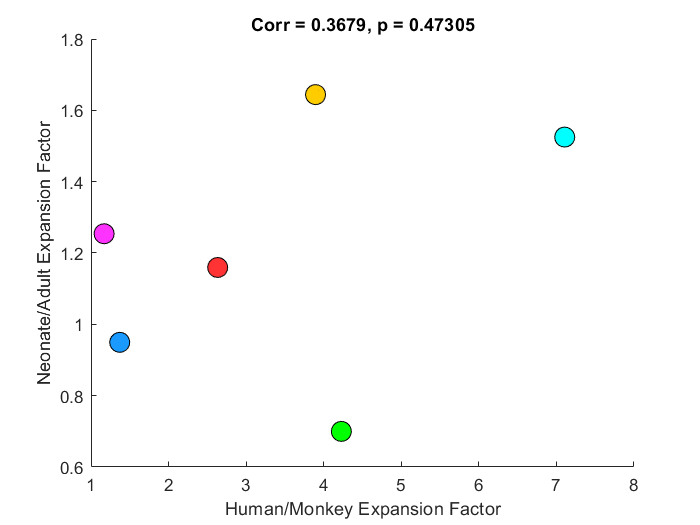

evccolor=[0.1 0.6 1];
v4color=[1 0.2 1];
ventralcolor=[1 0.2 0.2];
dorsalcolor=[1 .8 0];
parietalcolor=[0 1 1];
lateralcolor=[0 1 0];
human_colors = [evccolor;v4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];

figure();hold on;
for i = 1:size(data_monkey,1)
    plot(mean(data_monkey(i,:)),mean(data_neo(i,:)),'ko','MarkerFaceColor',human_colors(i,:),'MarkerSize',12)
end
xlabel('Human/Monkey Expansion Factor')
ylabel('Neonate/Adult Expansion Factor')
[r,p] = corr(mean(data_monkey,2),mean(data_neo,2));
title(['Corr = ',num2str(r),', p = ',num2str(p)])